# The effects of wave-induced ice breakup

In this script we investigate the re-distribution of the FSD due to wave-induced ice breakup. We currently (05/07/2022) believe that substantial amounts of ice is being broken up and moved to the smallest FSD category. We will later go on to compare the relative changes to the first FSD category.

% Get files
clear all
clc
close all
addpath functions
addpath /Users/noahday/GitHub/CICE-analyser/processing

historydir = '/Users/noahday/GitHub/CICE-plotting-tools/cases/monthwim/history/';%'/Volumes/NoahDay5TB/cases/wimoninit/history/';

a = dir([historydir '/*.nc']);
n_files = numel(a);

for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end

% Read in the data
sector = "SH";
for i = 1:n_files
    data.aice(:,:,i) = data_format_sector(filenames(i,:),"aice",sector);
    data.dafsd_latg(:,:,:,i) = data_format_sector(filenames(i,:),"dafsd_latg",sector);
    data.dafsd_latm(:,:,:,i) = data_format_sector(filenames(i,:),"dafsd_latm",sector);
    data.dafsd_newi(:,:,:,i) = data_format_sector(filenames(i,:),"dafsd_newi",sector);
    data.dafsd_weld(:,:,:,i) = data_format_sector(filenames(i,:),"dafsd_weld",sector);
    data.dafsd_wave(:,:,:,i) = data_format_sector(filenames(i,:),"dafsd_wave",sector);
end
[lat,lon] = get_grid(filenames(i,:),"aice");


NFSD = ncread(filenames(i,:),"NFSD");
lat_vec = reshape(lat,[],1);
lon_vec = reshape(lon,[],1);
c_min = -0.01;
c_max = 0.01;

f = figure;
subplot(2,2,1)
day = 6;
[w, a, output_data] = map_plot(data.dafsd_latg(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

title('dAFSD 1 due to lateral growth')
cmocean('balance',11)
caxis([c_min,c_max]);
subplot(2,2,2)
[w, a, output_data] = map_plot(data.dafsd_newi(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

title('dAFSD 1 due to new ice')
cmocean('balance',11)
caxis([c_min,c_max]);
subplot(2,2,3)
[w, a, output_data] = map_plot(data.dafsd_weld(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

title('dAFSD 1 due to welding')
cmocean('balance',11)
caxis([c_min/10,c_max/10]);
subplot(2,2,4)
[w, a, output_data] = map_plot(data.dafsd_wave(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

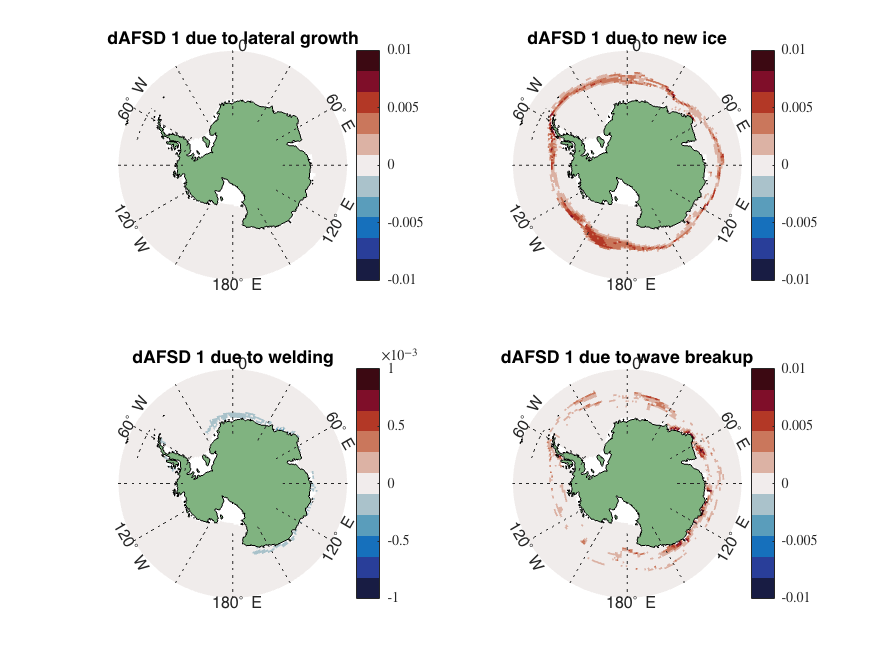

title('dAFSD 1 due to wave breakup')
cmocean('balance',11)
caxis([c_min,c_max]);

% July

f = figure;
subplot(2,2,1)
day = 7;
[w, a, output_data] = map_plot(data.dafsd_latg(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

title('dAFSD 1 due to lateral growth')
cmocean('balance',11)
caxis([c_min,c_max]);
subplot(2,2,2)
[w, a, output_data] = map_plot(data.dafsd_newi(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

title('dAFSD 1 due to new ice')
cmocean('balance',11)
caxis([c_min,c_max]);
subplot(2,2,3)
[w, a, output_data] = map_plot(data.dafsd_weld(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

title('dAFSD 1 due to welding')
cmocean('balance',11)
caxis([c_min/10,c_max/10]);
subplot(2,2,4)
[w, a, output_data] = map_plot(data.dafsd_wave(:,:,1,day).*NFSD(1),"dafsd_wave",sector); 

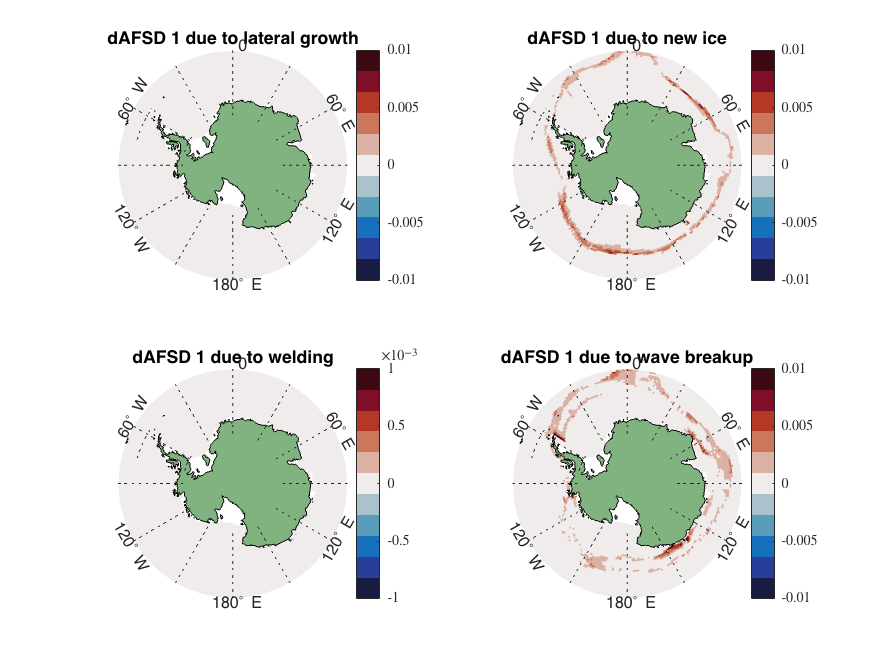

title('dAFSD 1 due to wave breakup')
cmocean('balance',11)
caxis([c_min,c_max]);